# Section 1.2 (Part 3)

In this activity, we will examine a system of linear equations that has an infinite number of solutions. We begin with an example.

# Example #1:

Solve the following system for $x$, $y$, and $z$.


$$\begin{array}{rcl}
y-z&=&4\\
2x+y+2z&=&4\\
2x+2y+z&=&8
\end{array}$$


**Solution:** Let's manipulate the system a bit to make clear the augmented matrix for the system.


$$\begin{array}{rcl}
0x+1y-1z&=&4\\
2x+1y+2z&=&4\\
2x+2y+1z&=&8
\end{array}$$


We write our augmented matrix and highlight the leading entry in row one.


$$\pmatrix{0 & [1] & -1 & 4\cr 2 & 1 & 2 & 4\cr 2 & 2 & 1 & 8}$$


The leading entry in row one is in column two, but the leading entries in rows two and three are not in columns to the right of the leading entry in row one, so, let's exchange rows one and three.


$$\pmatrix{0 & [1] & -1 & 4\cr 2 & 1 & 2 & 4\cr 2 & 2 & 1 & 8}\ \matrix{R_1\leftrightarrow R_3\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{2 & 2 & 1 & 8\cr 2 & 1 & 2 & 4\cr  0 & 1 & -1 & 4}$$


We can check this with Matlab. Enter matrix A.

A=[0 1 -1 4;2 1 2 4;2 2 1 8]

A =      0     1    -1     4
     2     1     2     4
     2     2     1     8


Save each row in the variables r1, r2, and r3.

r1=A(1,:)

r1 =      0     1    -1     4


r2=A(2,:)

r2 =      2     1     2     4


r3=A(3,:)

r3 =      2     2     1     8


Now, we exchanged rows one and three and left row two alone, so we can check this as follows.

A=[r3;r2;r1]

A =      2     2     1     8
     2     1     2     4
     0     1    -1     4


This agrees with our hand-calculations. So let's restore each row.

r1=A(1,:)

r1 =      2     2     1     8


r2=A(2,:)

r2 =      2     1     2     4


r3=A(3,:)

r3 =      0     1    -1     4


Now, let's highlight the leading entry in our new row one.


$$\pmatrix{[2] & 2 & 1 & 8\cr 2 & 1 & 2 & 4\cr  0 & 1 & -1 & 4}$$


Now we will use elementary row operations to zero out all entries below this highlighted term. Replace row two with the sum of itself and -1 times row one.


$$\pmatrix{[2] & 2 & 1 & 8\cr 2 & 1 & 2 & 4\cr  0 & 1 & -1 & 4}\ \matrix{~\cr R_2-R_1\cr ~}\qquad\longrightarrow\qquad \pmatrix{2 & 2 & 1 & 8\cr 0 & -1 & 1 & -4\cr  0 & 1 & -1 & 4}$$


Let's check this with Matlab. Rows one and three remain the same, but we replaced row two with $R_2-R_1$.

A=[r1;r2-r1;r3]

A =      2     2     1     8
     0    -1     1    -4
     0     1    -1     4


Again, this agrees with our hand-calculations, so let's restore the new rows in r1, r2, and r3.

r1=A(1,:)

r1 =      2     2     1     8


r2=A(2,:)

r2 =      0    -1     1    -4


r3=A(3,:)

r3 =      0     1    -1     4


Now, let's highlight the leading entry in row two.


$$\pmatrix{2 & 2 & 1 & 8\cr 0 & [-1] & 1 & -4\cr  0 & 1 & -1 & 4}$$


Now, we want to zero out all entries in the column below the highlighted leading term in row two. Replace row three with the sum of itself and row two.


$$\pmatrix{2 & 2 & 1 & 8\cr 0 & [-1] & 1 & -4\cr  0 & 1 & -1 & 4}\ \matrix{~\cr ~\cr R_3+R_2}\qquad\longrightarrow\qquad \pmatrix{2 & 2 & 1 & 8\cr 0 & -1 & 1 & -4\cr  0 & 0 & 0 & 0}$$


We can check this with Matlab. Rows one and two remain the same, but we replaced row three with $R_2+R_2$.

A=[r1;r2;r3+r2]

A =      2     2     1     8
     0    -1     1    -4
     0     0     0     0


This is the same as our hand-calculations. Now we can write the system of equations represented by this row echelon form. 


$$\begin{array}{rcl}
2x+2y+z&=&8\\
-y+z&=&-4\\
0z&=&0
\end{array}$$


Note that any values of $z$ will satisfy the last equation. That is, $z$ is "free" to be any number at all. We call $z$ a "free variable." 

**Back Substitution:** Because $z$ is a free variable, our goal is to use back substitution to solve for $x$ and $y$ in terms of the free variable $z$. We start by solving our secon equation for $y$ in terms of the free variable $z$.


$$\begin{array}{rcl}
-y+z&=&-4\\
-y&=&-z-4\\
y&=&z+4
\end{array}$$


Now we substitute $y=4+z$ into the first equation and solve for $x$ in terms of the free variable $z$


$$\begin{array}{rcl}
2x+2y+z&=&8\\
2x+2(z+4)+z&=&8\\
2x+3z+8&=&8\\
2x&=&-3z\\
x&=&-\frac32z
\end{array}$$


Hence, our final solution is


$$(x,y,z)=\left(-\frac32z,\ z+4,\ z\right)$$


where $z$ is free to be any number at all. For example, if we let $z=0$, then $(x,y,z)=(0,4,0)$. Does this point satisfy all three equations? Recall that our original equations were:


$$\begin{array}{rcl}
y-z&=&4\\
2x+y+2z&=&4\\
2x+2y+z&=&8
\end{array}$$


Let's check the point $(x,y,z)=(0,4,0)$ with Matlab.

x=0; y=4; z=0;
[y-z,2*x+y+2*z,2*x+2*y+z]

ans =      4     4     8


Note that we get 4, 4, and 8, which correspond to the right sides of each of our equations above, so this point does satisfy all three equations. Recall that our answer is:


$$(x,y,z)=\left(-\frac32z,\ z+4,\ z\right)$$


 If we let $z=-1$, then $(x,y,z)=\left(\frac32,3,-1\right)$. Does this point satisfy all three equations? Let's check it with matlab.

x=3/2; y=3; z=-1;
[y-z,2*x+y+2*z,2*x+2*y+z]

ans =      4     4     8


Again, we get 4, 4, and 8 which correspond to the right sides of each of our equations above, so this point also satisfies all three equations. Recall that our answer is:


$$(x,y,z)=\left(-\frac32z,\ z+4,\ z\right)$$


 If we let $z=1$, then $(x,y,z)=\left(-\frac32,5,1\right)$. Does this point satisfy all three equations? Let's check it with matlab.

x=-3/2; y=5; z=1;
[y-z,2*x+y+2*z,2*x+2*y+z]

ans =      4     4     8


Again, this checks. We can continue entering different values of z forever, demonstrating that this system has an infinite number of solutions. 

# Visualizing Our Answer

We showed above that the points $(0,4,0)$, $(3/2,3,-1)$, and $(-3/2,5,1)$ satisfy our system of equations. Because the $x$-values of these points are 0, 3/2, and $-3/2$, this makes us want to try 20 values between -2 and 2 for $x$.

x=linspace(-2,2,20);

Because the $y$-values of these points are 4, 3, and 5, this makes us want to try 20 values between 2 and 6 for $y$.

y=linspace(2,6,20);

Now, recall our system of equations.


$$\begin{array}{rcl}
y-z&=&4\\
2x+y+2z&=&4\\
2x+2y+z&=&8
\end{array}$$


Let's solve each equation for $z$.


$$\begin{array}{rcl}
z&=&y-4\\
z&=&2-x-\frac{y}{2}\\
z&=&8-2x-2y
\end{array}$$


Now, let's draw each plane represented by each equation.

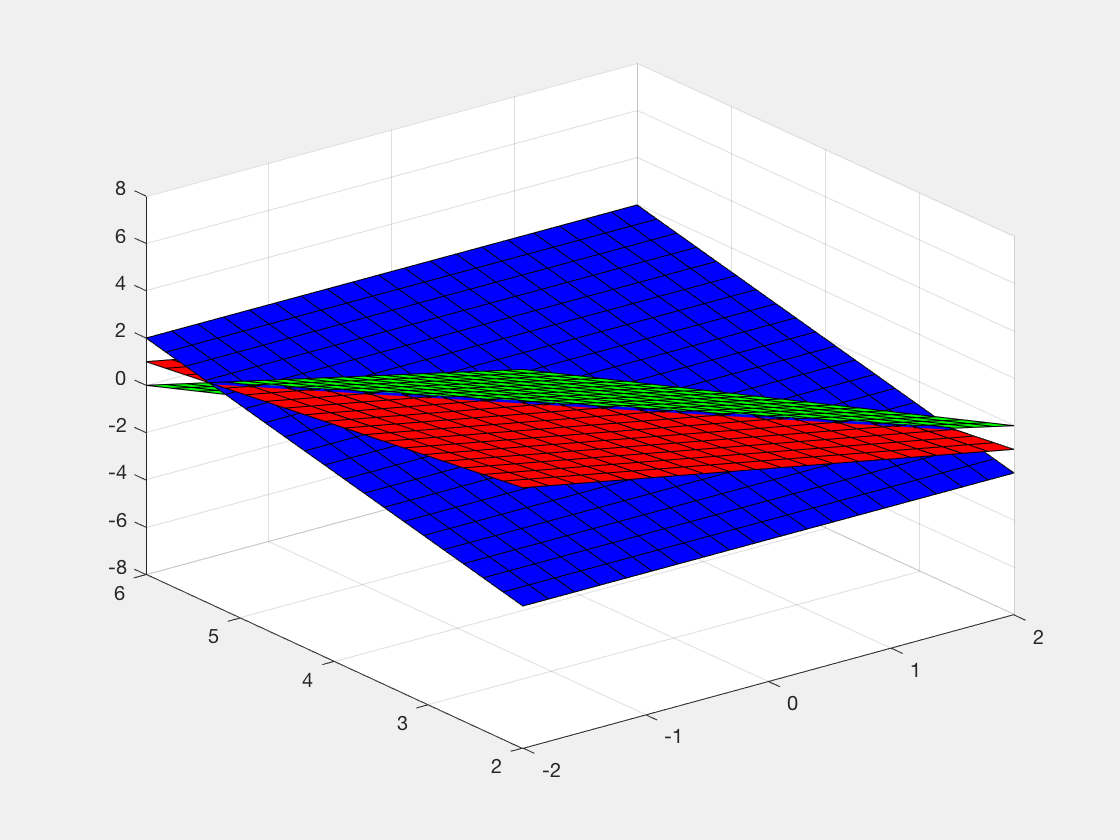

[X,Y]=meshgrid(x,y);
Z=Y-4;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=2-X-Y/2;
surf(X,Y,Z,'FaceColor','red')
Z=8-2*X-2*Y;
surf(X,Y,Z,'FaceColor','green')
hold off
rotate3d on

After rotating the image for a bit, we made this final decision for our view.

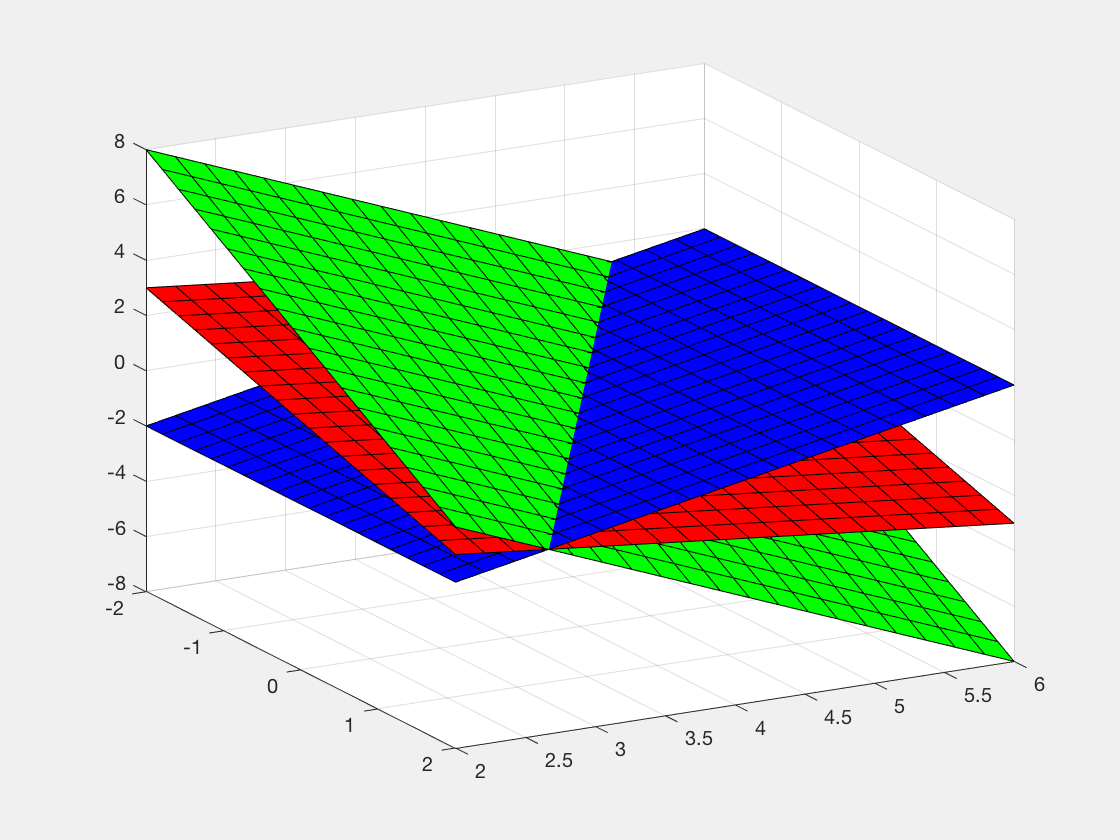

[X,Y]=meshgrid(x,y);
Z=Y-4;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=2-X-Y/2;
surf(X,Y,Z,'FaceColor','red')
Z=8-2*X-2*Y;
surf(X,Y,Z,'FaceColor','green')
hold off
view(61,22)

Note that the three planes appear to intersect in a line, which is an infinite set of points. Recall that our answer was $(x,y,z)=(-3z/2,z+4,z)$, where $z$ was free to be any number at all. Because we chose


$$-2\le x\le 2$$


above to draw our planes, and because our solution tells us that $x=-3z/2$, we can write:


$$\begin{array}{c}
-2\le -\frac32z\le 2\\
\frac43\ge z\ge -\frac43
\end{array}$$


Therefore, we will use $z$-values such that $-4/3\le z\le 4/3$ to add an infinite number of solutions to our image.

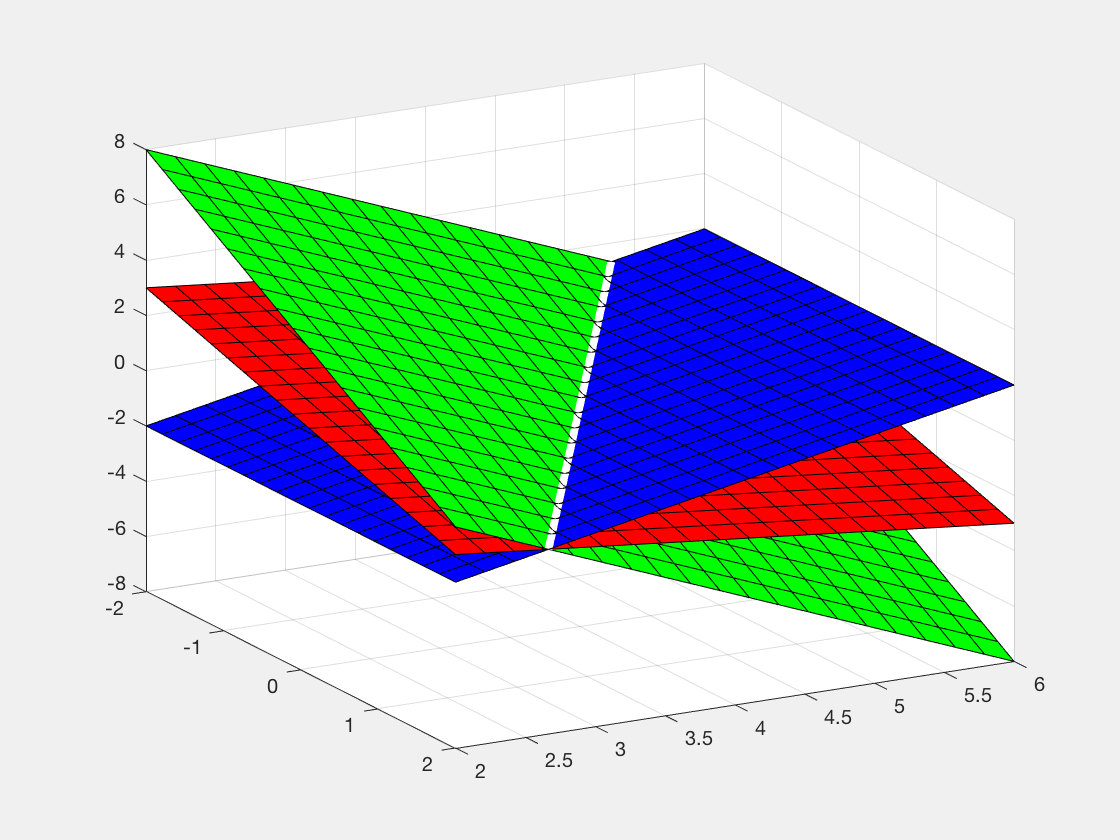

[X,Y]=meshgrid(x,y);
Z=Y-4;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=2-X-Y/2;
surf(X,Y,Z,'FaceColor','red')
Z=8-2*X-2*Y;
surf(X,Y,Z,'FaceColor','green')
z=linspace(-4/3,4/3);
x=-3*z/2;
y=z+4;
plot3(x,y,z,'LineWidth',4,'Color','white')
hold off
view(61,22)

The planes intersect on the white line we have drawn. What about our points $(0,4,0)$, $(3/2,3,-1)$, and $(-3/2,5,1)$we used above? Do they lie on this line?

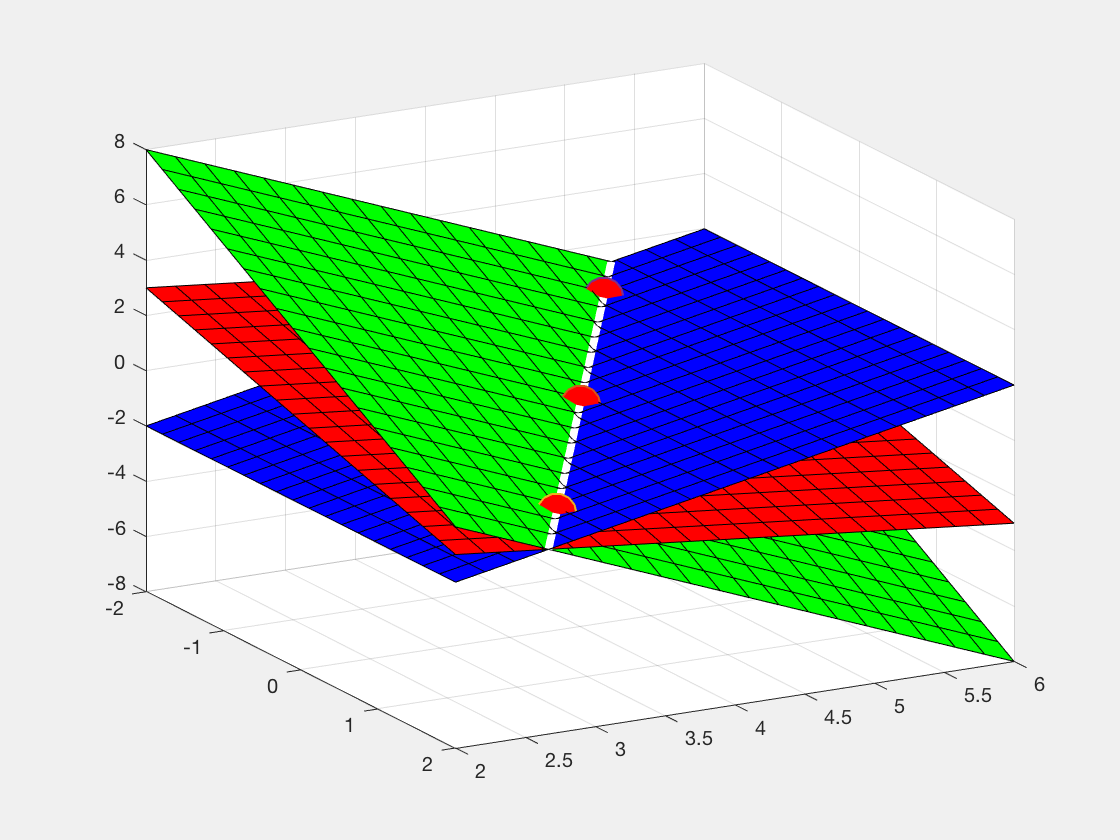

x=linspace(-2,2,20);
y=linspace(2,6,20);
[X,Y]=meshgrid(x,y);
Z=Y-4;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=2-X-Y/2;
surf(X,Y,Z,'FaceColor','red')
Z=8-2*X-2*Y;
surf(X,Y,Z,'FaceColor','green')
z=linspace(-4/3,4/3);
x=-3*z/2;
y=z+4;
plot3(x,y,z,'LineWidth',4,'Color','white')
plot3(0,4,0,'Marker','o','MarkerSize',20,'MarkerFaceColor','red')
plot3(3/2,3,-1,'Marker','o','MarkerSize',20,'MarkerFaceColor','red')
plot3(-3/2,5,1,'Marker','o','MarkerSize',20,'MarkerFaceColor','red')
hold off
view(61,22)

We've provided strong visual evidence that we have solved this system properly. :-)